close all
clear
clc

Filterparameter:

% Filterordnung
N = 2;
N_b = 1;

% Abtastfrequenz für Audioanwendungen in Hz
fs = 44100; % CD-Audio
% fs = 48000; % Studio Audio

% Grenzfrequenzen (in Hz)
fc_lp = 1000;          % Tiefpass
fc_hp = 1000;          % Hochpass
fc_bp_l = 500;
fc_bp_h = 2000;        % Bandpass
fc_bs_l = 500;
fc_bs_h = 2000;        % Bandsperre

% Normierte Frequenzen (digital)
Wc_lp = fc_lp/(fs/2);
Wc_hp = fc_hp/(fs/2);
Wc_bp = [fc_bp_l/(fs/2),fc_bp_h/(fs/2)];
Wc_bs = [fc_bs_l/(fs/2),fc_bs_h/(fs/2)];

% Ripples für Filter
Rp = 1;  % Durchlasswelligkeit [dB]
Rs = 80; % Sperrdämpfung [dB]

% Res. FFT
fft_res = 1024;

Tiefpass Filter:

% Butterworth TP
[blp_b, blp_a] = butter(N, Wc_lp, 'low');
disp(['Butterworth TP: b = [', num2str(blp_b, ' %.6f'), '], a = [', num2str(blp_a, ' %.6f'), ']'])

Butterworth TP: b = [0.004604 0.009208 0.004604], a = [1.000000 -1.799096  0.817512]


% Chebyshev Typ I TP
[c1lp_b,c1lp_a] = cheby1(N, Rp, Wc_lp, 'low');
disp(['Chebyshev Typ I TP: b = [', num2str(c1lp_b, ' %.6f'), '], a = [', num2str(c1lp_a, ' %.6f'), ']'])

Chebyshev Typ I TP: b = [0.004616 0.009232 0.004616], a = [1.000000 -1.834750  0.855467]


% Chebyshev Typ II TP
[c2lp_b,c2lp_a] = cheby1(N, Rs, Wc_lp, 'low');
disp(['Chebyshev Typ II TP: b = [', num2str(c2lp_b, ' %.6f'), '], a = [', num2str(c2lp_a, ' %.6f'), ']'])

Chebyshev Typ II TP: b = [0.000000 0.000001 0.000000], a = [1.000000 -1.989832  0.999990]


% Elliptischer TP
[elp_b, elp_a] = ellip(N, Rp, Rs, Wc_lp, 'low');
disp(['Elliptischer TP: b = [', num2str(elp_b, ' %.6f'), '], a = [', num2str(elp_a, ' %.6f'), ']'])

Elliptischer TP: b = [0.004709 0.009048 0.004709], a = [1.000000 -1.834757  0.855475]


Frequenzgänge berechnen:

[H_butter_LP, f_LP] = freqz(blp_b, blp_a, fft_res, fs);
[H_cheby1_LP, ~] = freqz(c1lp_b, c1lp_a, fft_res, fs);
[H_cheby2_LP, ~] = freqz(c2lp_b, c2lp_a, fft_res, fs);
[H_ellip_LP, ~]  = freqz(elp_b, elp_a, fft_res, fs);

Plot:

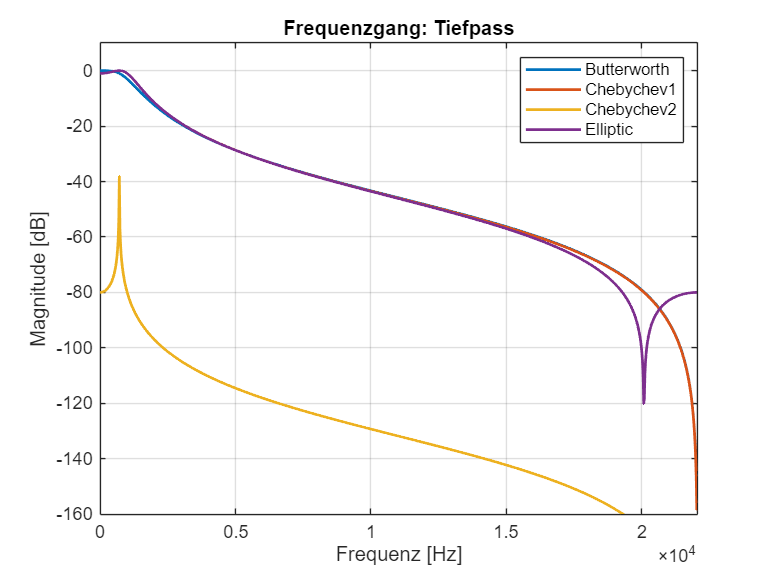

figure;
plot(f_LP, 20*log10(abs(H_butter_LP)), 'LineWidth', 1.5); hold on;
plot(f_LP, 20*log10(abs(H_cheby1_LP)), 'LineWidth', 1.5);
plot(f_LP, 20*log10(abs(H_cheby2_LP)), 'LineWidth', 1.5);
plot(f_LP, 20*log10(abs(H_ellip_LP)),  'LineWidth', 1.5);

grid on;
xlabel('Frequenz [Hz]');
ylabel('Magnitude [dB]');
title('Frequenzgang: Tiefpass');
legend('Butterworth', 'Chebychev1', 'Chebychev2', 'Elliptic');
xlim([0 fs/2]); % bis Nyquist
ylim([-160 10]); % Optional: Y-Achse für dB

Hochpass Filter:

% Butterworth HP
[bhp_b, bhp_a] = butter(N, Wc_hp, 'high');
disp(['Butterworth HP: b = [', num2str(bhp_b, ' %.6f'), '], a = [', num2str(bhp_a, ' %.6f'), ']'])

Butterworth HP: b = [0.904152 -1.808304  0.904152], a = [1.000000 -1.799096  0.817512]


% Chebyshev Typ I HP
[c1hp_b,c1hp_a] = cheby1(N, Rp, Wc_hp, 'high');
disp(['Chebyshev Typ I HP: b = [', num2str(c1hp_b, ' %.6f'), '], a = [', num2str(c1hp_a, ' %.6f'), ']'])

Chebyshev Typ I HP: b = [0.828556 -1.657111  0.828556], a = [1.000000 -1.850722  0.867897]


% Chebyshev Typ II HP
[c2hp_b,c2hp_a] = cheby1(N, Rs, Wc_hp, 'high');
disp(['Chebyshev Typ II HP: b = [', num2str(c2hp_b, ' %.6f'), '], a = [', num2str(c2hp_a, ' %.6f'), ']'])

Chebyshev Typ II HP: b = [0.000099 -0.000198  0.000099], a = [1.000000 -1.959655  0.999980]


% Elliptischer HP
[ehp_b, ehp_a] = ellip(N, Rp, Rs, Wc_hp, 'high');
disp(['Elliptischer HP: b = [', num2str(ehp_b, ' %.6f'), '], a = [', num2str(ehp_a, ' %.6f'), ']'])

Elliptischer HP: b = [0.828562 -1.657123  0.828562], a = [1.000000 -1.850736  0.867910]


Frequenzgänge berechnen:

[H_butter_HP, f_HP] = freqz(bhp_b, bhp_a, fft_res, fs);
[H_cheby1_HP, ~] = freqz(c1hp_b, c1hp_a, fft_res, fs);
[H_cheby2_HP, ~] = freqz(c2hp_b, c2hp_a, fft_res, fs);
[H_ellip_HP, ~]  = freqz(ehp_b, ehp_a, fft_res, fs);

Plot:

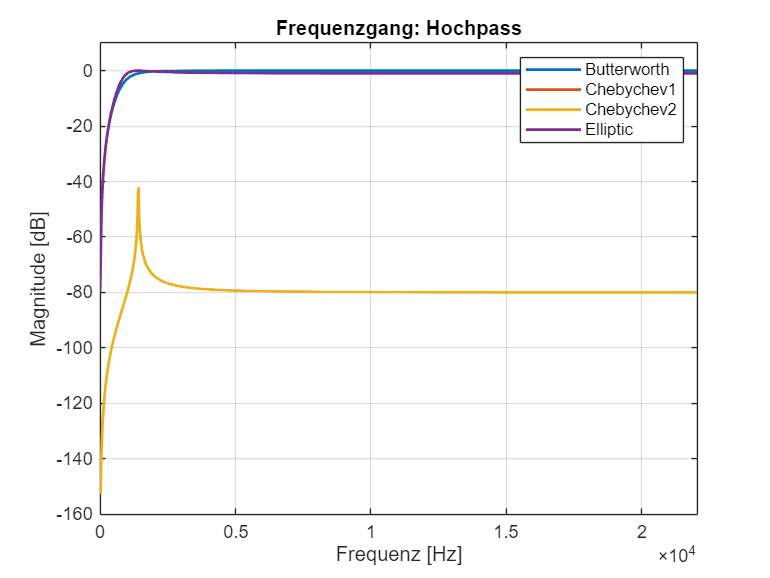

figure;
plot(f_HP, 20*log10(abs(H_butter_HP)), 'LineWidth', 1.5); hold on;
plot(f_HP, 20*log10(abs(H_cheby1_HP)), 'LineWidth', 1.5);
plot(f_HP, 20*log10(abs(H_cheby2_HP)), 'LineWidth', 1.5);
plot(f_HP, 20*log10(abs(H_ellip_HP)),  'LineWidth', 1.5);

grid on;
xlabel('Frequenz [Hz]');
ylabel('Magnitude [dB]');
title('Frequenzgang: Hochpass');
legend('Butterworth', 'Chebychev1', 'Chebychev2', 'Elliptic');
xlim([0 fs/2]); % bis Nyquist
ylim([-160 10]); % Optional: Y-Achse für dB

Bandpass Filter:

% Butterworth BP
[bbp_b, bbp_a] = butter(N_b, Wc_bp, 'bandpass');
disp(['Butterworth BP: b = [', num2str(bbp_b, ' %.6f'), '], a = [', num2str(bbp_a, ' %.6f'), ']'])

Butterworth BP: b = [0.096874  0.000000 -0.096874], a = [1.000000 -1.787880  0.806252]


% Chebyshev Typ I BP
[c1bp_b,c1bp_a] = cheby1(N_b, Rp, Wc_bp, 'bandpass');
disp(['Chebyshev Typ I BP: b = [', num2str(c1bp_b, ' %.6f'), '], a = [', num2str(c1bp_a, ' %.6f'), ']'])

Chebyshev Typ I BP: b = [0.174100  0.000000 -0.174100], a = [1.000000 -1.634998  0.651799]


% Chebyshev Typ II BP
[c2bp_b,c2bp_a] = cheby1(N_b, Rs, Wc_bp, 'bandpass');
disp(['Chebyshev Typ II BP: b = [', num2str(c2bp_b, ' %.6f'), '], a = [', num2str(c2bp_a, ' %.6f'), ']'])

Chebyshev Typ II BP: b = [0.000011  0.000000 -0.000011], a = [1.000000 -1.979636  0.999979]


% Elliptischer BP
[ebp_b, ebp_a] = ellip(N_b, Rp, Rs, Wc_bp, 'bandpass');
disp(['Elliptischer BP: b = [', num2str(ebp_b, ' %.6f'), '], a = [', num2str(ebp_a, ' %.6f'), ']'])

Elliptischer BP: b = [0.174100 -0.000000 -0.174100], a = [1.000000 -1.634998  0.651799]


Frequenzgänge berechnen:

[H_butter_BP, f_BP] = freqz(bbp_b, bbp_a, fft_res, fs);
[H_cheby1_BP, ~] = freqz(c1bp_b, c1bp_a, fft_res, fs);
[H_cheby2_BP, ~] = freqz(c2bp_b, c2bp_a, fft_res, fs);
[H_ellip_BP, ~]  = freqz(ebp_b, ebp_a, fft_res, fs);

Plot:

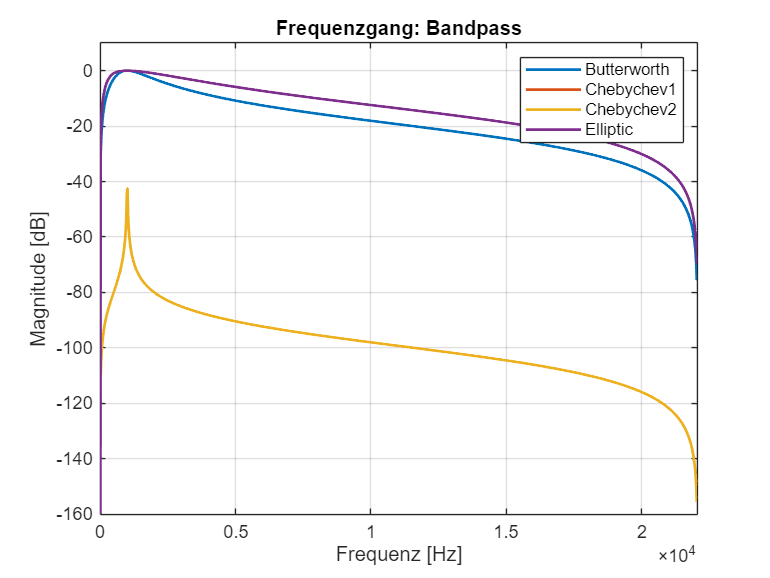

figure;
plot(f_BP, 20*log10(abs(H_butter_BP)), 'LineWidth', 1.5); hold on;
plot(f_BP, 20*log10(abs(H_cheby1_BP)), 'LineWidth', 1.5);
plot(f_BP, 20*log10(abs(H_cheby2_BP)), 'LineWidth', 1.5);
plot(f_BP, 20*log10(abs(H_ellip_BP)),  'LineWidth', 1.5);

grid on;
xlabel('Frequenz [Hz]');
ylabel('Magnitude [dB]');
title('Frequenzgang: Bandpass');
legend('Butterworth', 'Chebychev1', 'Chebychev2', 'Elliptic');
xlim([0 fs/2]); % bis Nyquist
ylim([-160 10]); % Optional: Y-Achse für dB

Bandstop Filter:

% Butterworth BS
[bbs_b, bbs_a] = butter(N_b, Wc_bs, 'stop');
disp(['Butterworth BS: b = [', num2str(bbs_b, ' %.6f'), '], a = [', num2str(bbs_a, ' %.6f'), ']'])

Butterworth BS: b = [0.903126 -1.787880  0.903126], a = [1.000000 -1.787880  0.806252]


% Chebyshev Typ I BS
[c1bs_b,c1bs_a] = cheby1(N_b, Rp, Wc_bs, 'stop');
disp(['Chebyshev Typ I BS: b = [', num2str(c1bs_b, ' %.6f'), '], a = [', num2str(c1bs_a, ' %.6f'), ']'])

Chebyshev Typ I BS: b = [0.948243 -1.877197  0.948243], a = [1.000000 -1.877197  0.896486]


% Chebyshev Typ II BS
[c2bs_b,c2bs_a] = cheby1(N_b, Rs, Wc_bs, 'stop');
disp(['Chebyshev Typ II BS: b = [', num2str(c2bs_b, ' %.6f'), '], a = [', num2str(c2bs_a, ' %.6f'), ']'])

Chebyshev Typ II BS: b = [0.000931 -0.001844  0.000931], a = [1.000000 -0.001844 -0.998137]


% Elliptischer BS
[ebs_b, ebs_a] = ellip(N_b, Rp, Rs, Wc_bs, 'stop');
disp(['Elliptischer BS: b = [', num2str(ebs_b, ' %.6f'), '], a = [', num2str(ebs_a, ' %.6f'), ']'])

Elliptischer BS: b = [0.948243 -1.877197  0.948243], a = [1.000000 -1.877197  0.896486]


Frequenzgänge berechnen:

[H_butter_BS, f_BS] = freqz(bbs_b, bbs_a, fft_res, fs);
[H_cheby1_BS, ~] = freqz(c1bs_b, c1bs_a, fft_res, fs);
[H_cheby2_BS, ~] = freqz(c2bs_b, c2bs_a, fft_res, fs);
[H_ellip_BS, ~]  = freqz(ebs_b, ebs_a, fft_res, fs);

Plot:

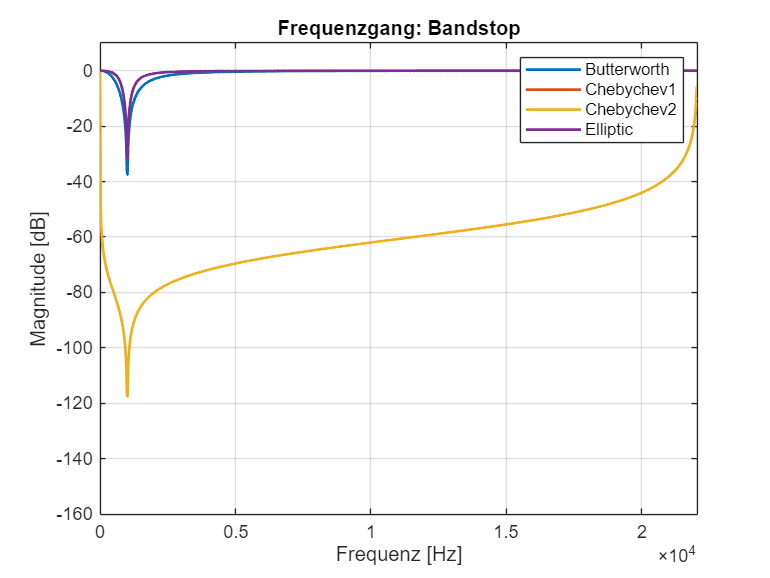

figure;
plot(f_BS, 20*log10(abs(H_butter_BS)), 'LineWidth', 1.5); hold on;
plot(f_BS, 20*log10(abs(H_cheby1_BS)), 'LineWidth', 1.5);
plot(f_BS, 20*log10(abs(H_cheby2_BS)), 'LineWidth', 1.5);
plot(f_BS, 20*log10(abs(H_ellip_BS)),  'LineWidth', 1.5);

grid on;
xlabel('Frequenz [Hz]');
ylabel('Magnitude [dB]');
title('Frequenzgang: Bandstop');
legend('Butterworth', 'Chebychev1', 'Chebychev2', 'Elliptic');
xlim([0 fs/2]); % bis Nyquist
ylim([-160 10]); % Optional: Y-Achse für dB